# **Introductory script illustrating usage of the @display and @scene ISETBio objects.  **

*This tutorial generates an ISETBio scene representing a Gabor stimulus and a realization of that scene on a particular display. Along the way, we illustrate usage of the @display and @scene ISETBio objects and identify key points.*

**See also**: 

- `t_coneIsomerizationsFromSceneOnDisplay.mlx`

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2018*

# **Step 1.** Create a display object

**Initialize a display object**

Start with an existing display specification, here an Apple LCD display, and place it 57 cm away from the subject

presentationDisplay = displayCreate('LCD-Apple', 'viewing distance', 0.57);

**Three key properties of a display's primaries (guns):**

- spectral power distribution (SPD), which is the emmitted power as a function of wavelength

- gamma curve, which is the relationship between the linear (input) primary value and the activation (output) of the primary 

- chromaticity coordinates and maximum luminance

In ISETBio, we interact with objects via **set **(write) and **get **(read) functions. These functions accept input arguments specifiying the property whose value we want to write/ead. We can get some information about what the available property names are by typing **doc** and the setter/getter function name, for example, **doc displayGet**

## Step 1.1 **Retrieve and plot the display primaries' spectral power distribution (SPD)**

The SPD represents the **spectral radiance** of the display's RGB guns, which is the radiance, $R$, emitted at each wavelength, $\lambda$.

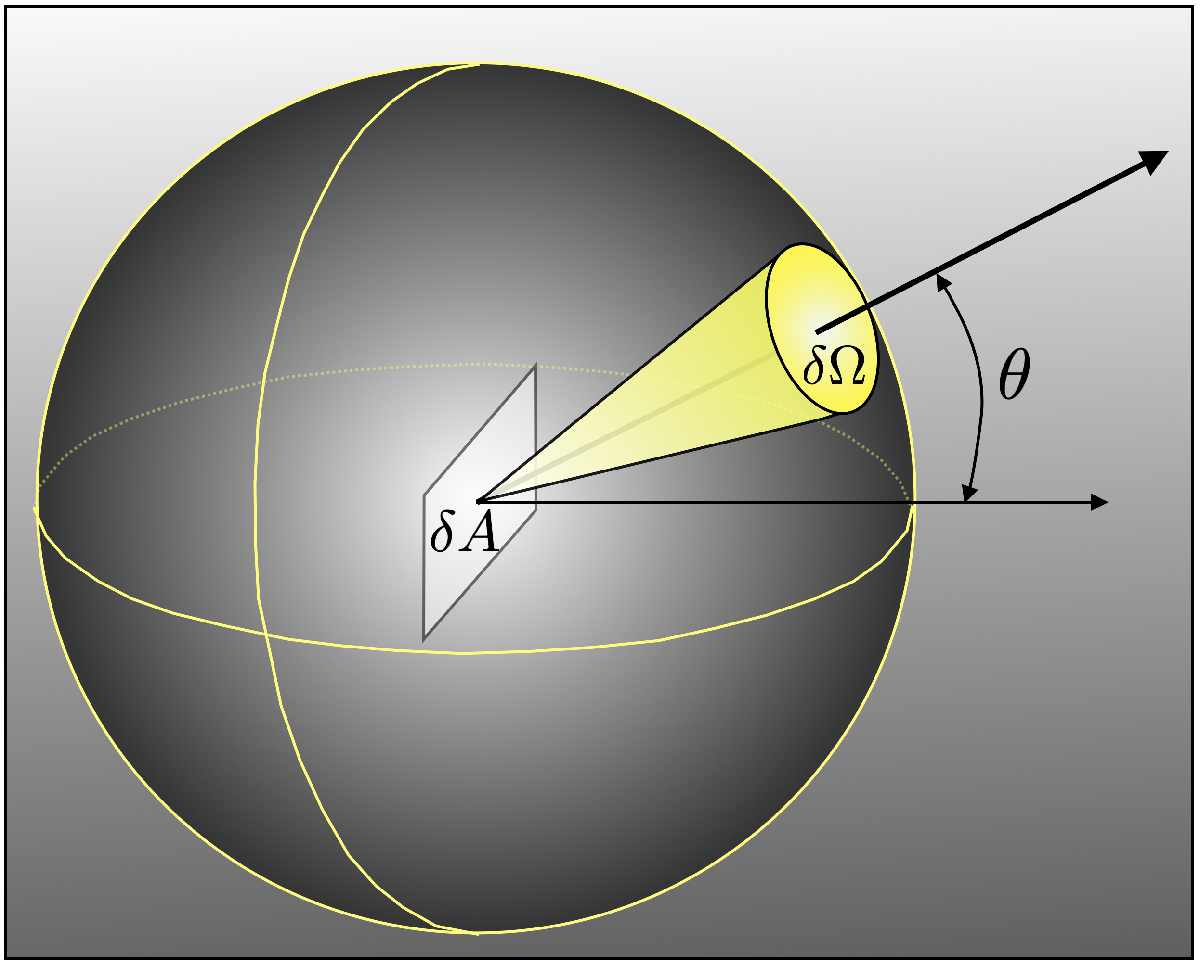

The radiance $R$ quantifies the radiometric power, P,  (energy flux) emitted by a light source that passes though a unit solid angle, $\delta \Omega$, per unit projected area of the source onto the aperture, $\delta A \cdot cos(\theta)$. The units of specral radiance are $Watts \cdot sr^{-1} \cdot m^{-2} \cdot nm^{-1}$.

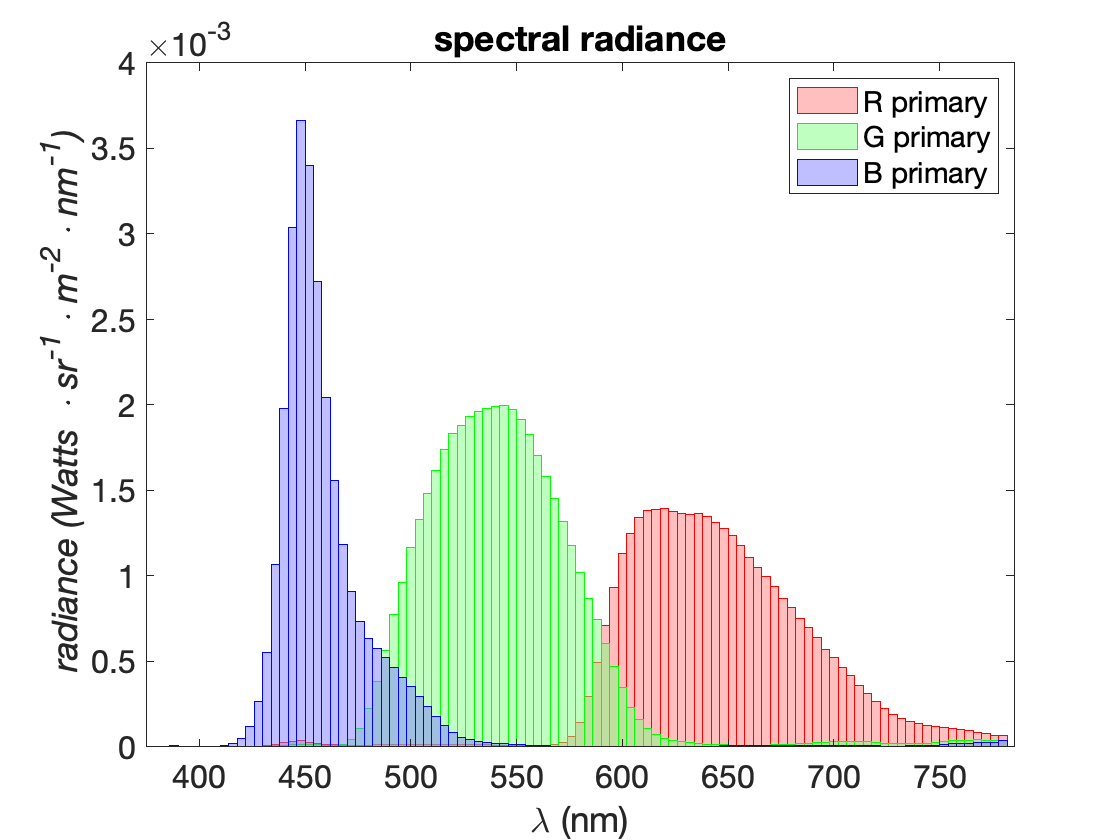

% retrieve the wavelength support
wavelengthSupport = displayGet(presentationDisplay, 'wave');
% retrieve the SPDs (spectral radiance)
spds = displayGet(presentationDisplay, 'spd primaries');
% display the SPDs
visualizeDisplaySPD(wavelengthSupport, spds);

## Step 1.2 Retrieve and plot the display's gamma funcions (LUTs)

Displays typically apply a gamma-function (power with exponent near 2.5) to the input RGB values (out = input$^{2.5}$) to produce the output light intensity. This gamma function is also called the display's LUT. When generating stimuli with desired RGB primary values we must corrected for this gamma function, by passing the RGB values though the inverse of the display's LUT. The image below [Brainard, D.H., Pelli, D.G. & Robson, T. 2002 Display characterization. In Encylopedia of Imaging Science and Technology (ed. J.P. Hornak), pp. 172-188. New York, Wiley.] illustrates the idea that digital signals passed to display channles typically pass through a static non-linearity (gamma function) on their way to generating the power emitted by each channel.

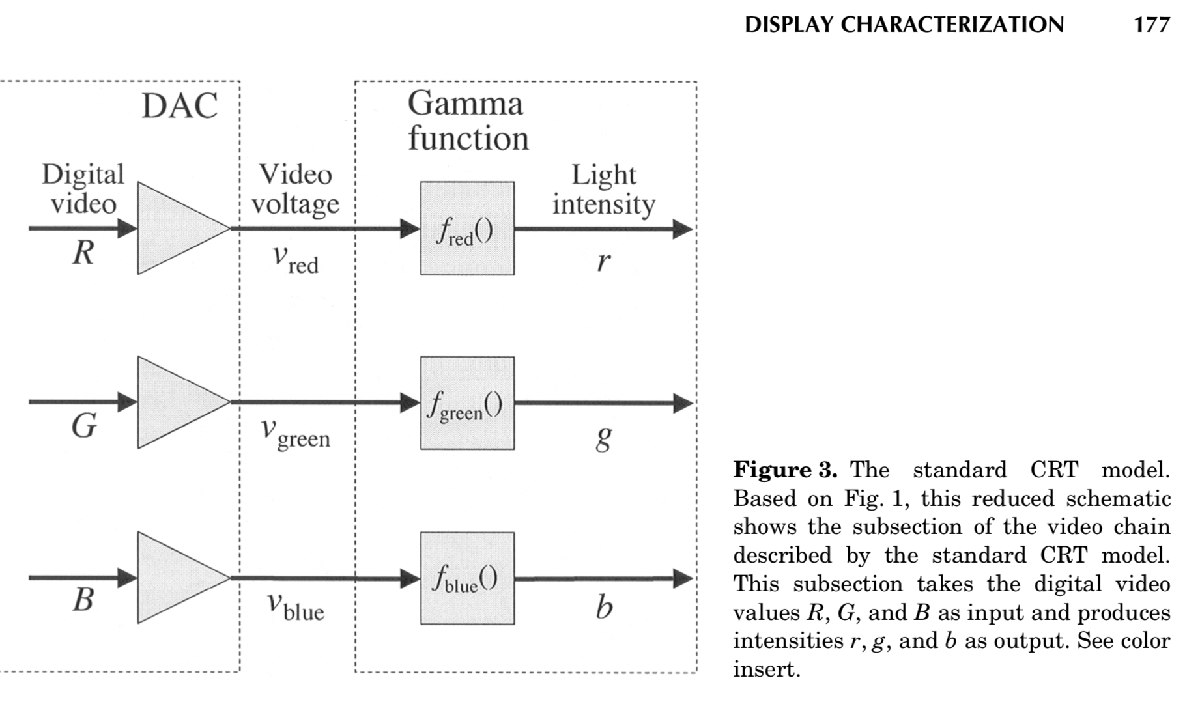

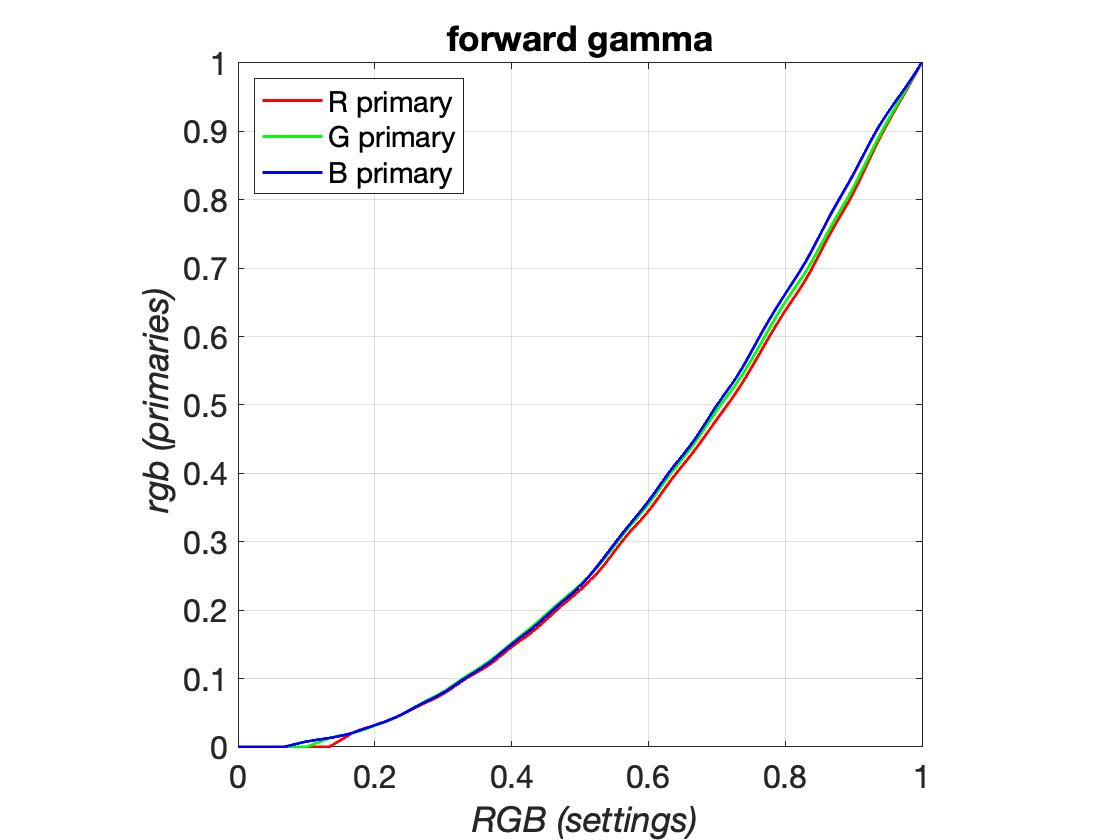

% retrieve the gamma table, or LUT, which determines how input RGB values
% are mapped to light intensity rgb values
gammaTable = displayGet(presentationDisplay, 'gamma table');
% display the LUT
visualizeDisplayLUT(gammaTable, 'forward');

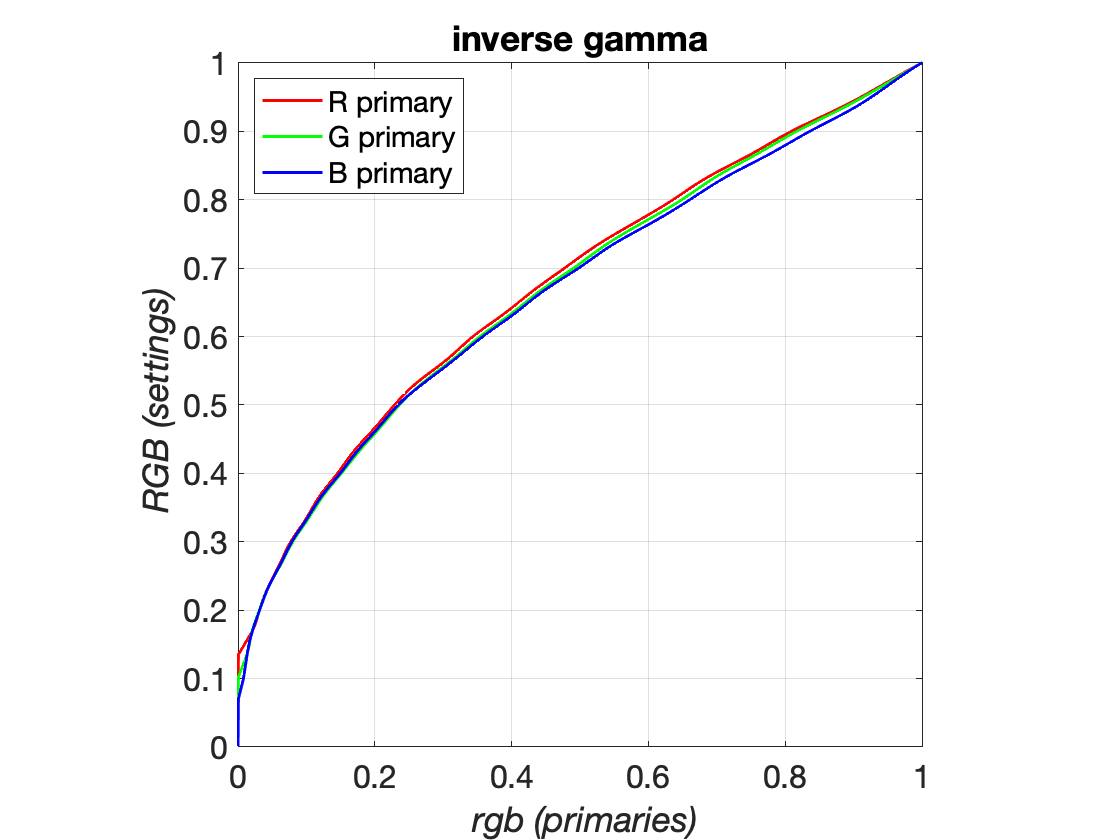

% Extract the inverse gamma table 
inverseGammaTable = displayGet(presentationDisplay, 'inverse gamma');
% display the LUT
visualizeDisplayLUT(inverseGammaTable, 'inverse');

## Step 1.3 Retrieve and plot the display's gamut

The SPDs of the display's R,G,B primaries determine the display's **gamut**, which is the range of colors and luminances that can be realized by the display. Here the gamut is represented in the CIE xy chromaticity diagram. This is a standard colorimetric representation used in science and industry, and it is introduced in many texts and chapters [see for example Brainard, D.H. & Stockman, A. 2010 Colorimetry. In The Optical Society of America Handbook of Optics, 3rd edition, Volume III: Vision and Vision Optics (eds. M. Bass et al.), pp. 10.11-10.56. New York, McGraw Hill.]

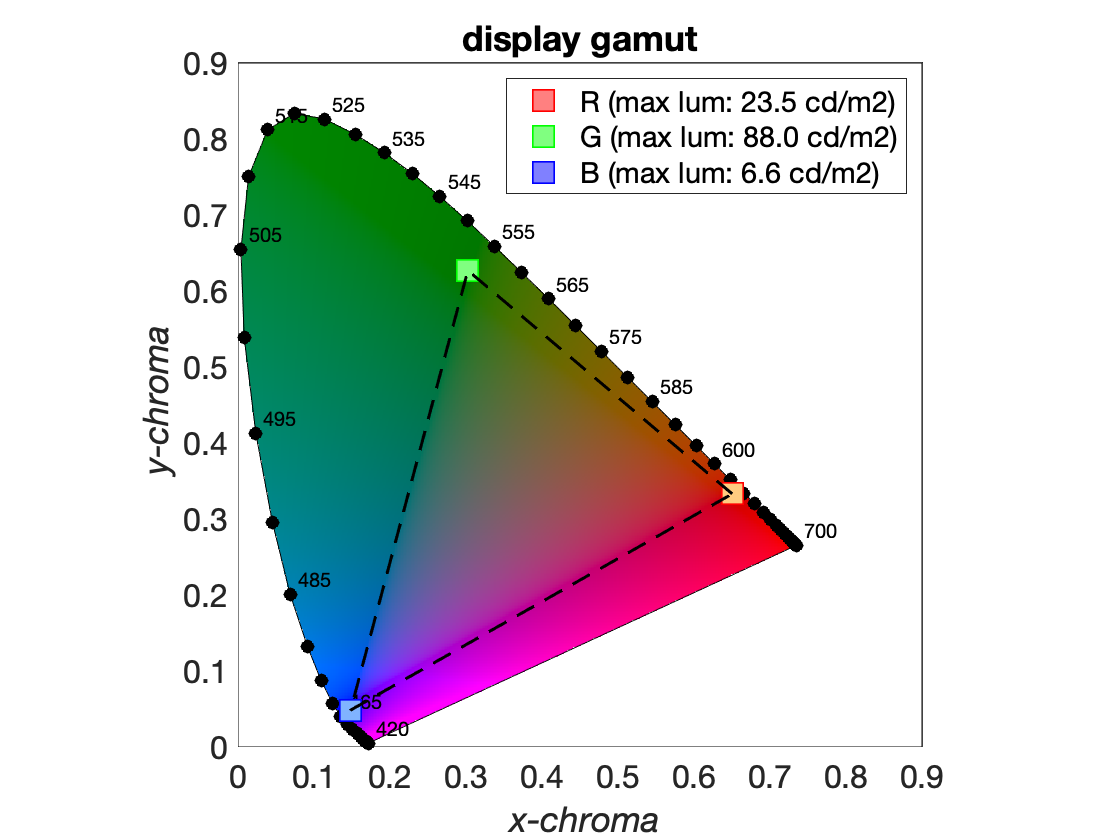

% retrieve the XYZ color space coordinates (tristimulus values) of the display's RGB primaries.
% The CIE XYZ color space is a device-independent color space in which any color visible by 
% normal human observers can be represented as an (X,Y,Z) triplet (the color's tristimulus
% values).
primariesXYZ = displayGet(presentationDisplay, 'primaries xyz');
% plot the display's chromaticity coordinates and maximum luminances on the
% CIE diagram
visualizeDisplayGamut(primariesXYZ);

# **Step 2.** Create a scene object describing the stimulus

## Step 2.1 Specify parameters for a desired stimulus

Here we specify various parameters for an achromatic Gabor stimulus. This scene is realized in a display independend form.

%% parameter struct for a high-frequency Gabor stimulus 
stimParams = struct(...
    'spatialFrequencyCyclesPerDeg', 10, ... % 10 cycles/deg
    'orientationDegs', 0, ...               % 45 degrees
    'phaseDegs', 90, ...                    % spatial phase degrees
    'sizeDegs', 0.4, ...                    % 0.4 x 0.4 size
    'sigmaDegs', 0.2/3, ...                 % sigma of Gaussian envelope
    'contrast', 0.6,...                     % 0.6 Michelson contrast
    'meanLuminanceCdPerM2', 40, ...         % 40 cd/m2 mean luminance
    'pixelsAlongWidthDim', [], ...          % pixels- width dimension
    'pixelsAlongHeightDim', [] ...          % pixel- height dimension
    );

## Step 2.2 Compute the number of pixels that the stimulus would occupy on the presentation display 

Note that we did not specify the number of pixels along the width and height because these depend on the size of pixels in the presentation display. Lets compute this now.

% retrieve the display's pixel size 
displayPixelSizeMeters = displayGet(presentationDisplay, 'sample spacing');
% retrieve the display's viewing distance
viewingDistanceMeters = displayGet(presentationDisplay, 'distance');
% compute pixel size in visual degrees
displayPixelSizeDegrees = ...
    2 * atand(0.5*displayPixelSizeMeters/viewingDistanceMeters);
% divide the stimulus size in degrees by the pixel size in degrees to get 
% the number of stimulus pixels
stimParams.pixelsAlongWidthDim = ...
    round(stimParams.sizeDegs/displayPixelSizeDegrees(1));
stimParams.pixelsAlongHeightDim = ...
    round(stimParams.sizeDegs/displayPixelSizeDegrees(2));

## Step 2.3 Generate an ISETBio scene based on these parameters 

scene = generateGaborScene();
% Place the scene at the same distance as the display
scene = sceneSet(scene, 'distance', viewingDistanceMeters);
% Give the scene a name
scene = sceneSet(scene, 'name', 'GABOR SCENE');

## Step 2.4 Plot an RGB rendition of the scene

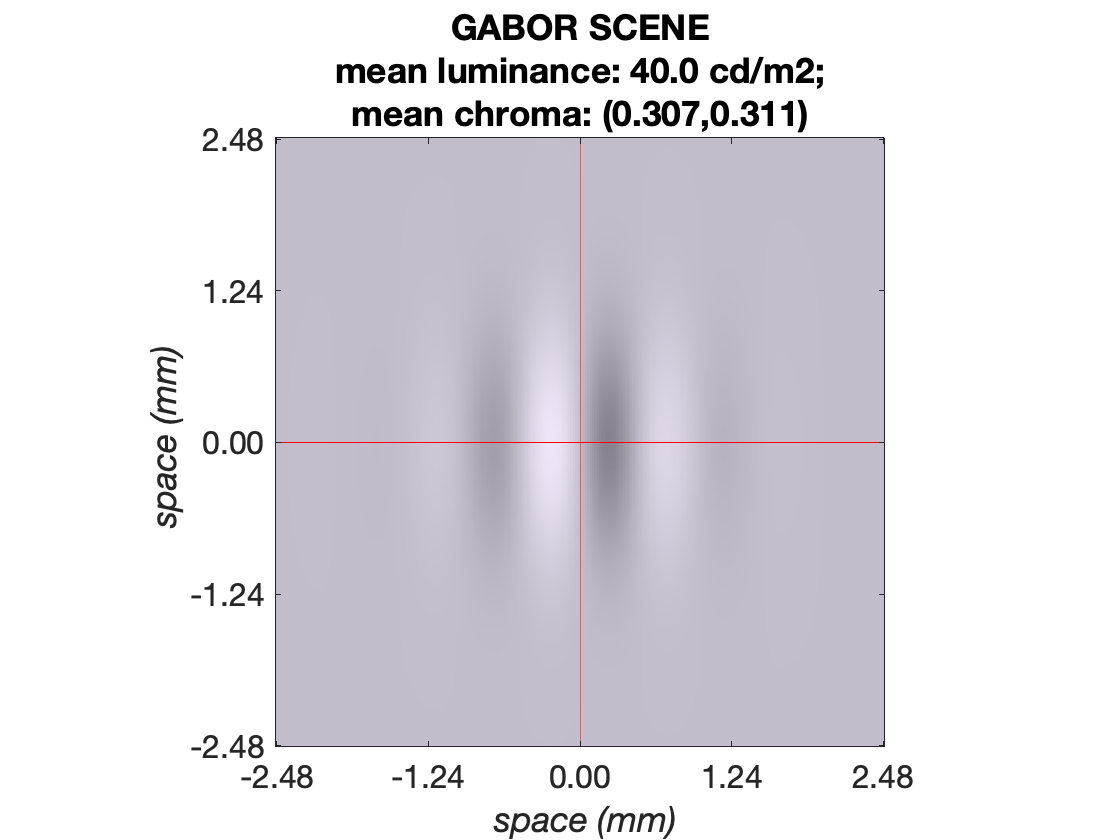

% retrieve the spatial support of the scene (in millimeters)
spatialSupportMilliMeters = sceneGet(scene, 'spatial support', 'mm');
% retrieve the sRGB components of the scene (just for visualization)
sceneRGBsettings = sceneGet(scene, 'rgb image');
% retrieve the XYZ tristimulus components of the scene
XYZmap = sceneGet(scene, 'xyz');
% compute the xy-chroma and the luminance maps
luminanceMap = squeeze(XYZmap(:,:,2));
xMap = squeeze(XYZmap(:,:,1))./sum(XYZmap,3);
yMap = squeeze(XYZmap(:,:,2))./sum(XYZmap,3);
% Compute mean luminance and mean chromaticity
meanLuminance = mean(luminanceMap(:));
meanChromaticity = [mean(xMap(:)) mean(yMap(:))];
% visualize the scene as RGB
visualizeSceneRGB(spatialSupportMilliMeters, 'mm', sceneRGBsettings, ...
    meanLuminance, meanChromaticity, sceneGet(scene, 'name'));

## Step 2.4 Plot the spectral radiance of the scene

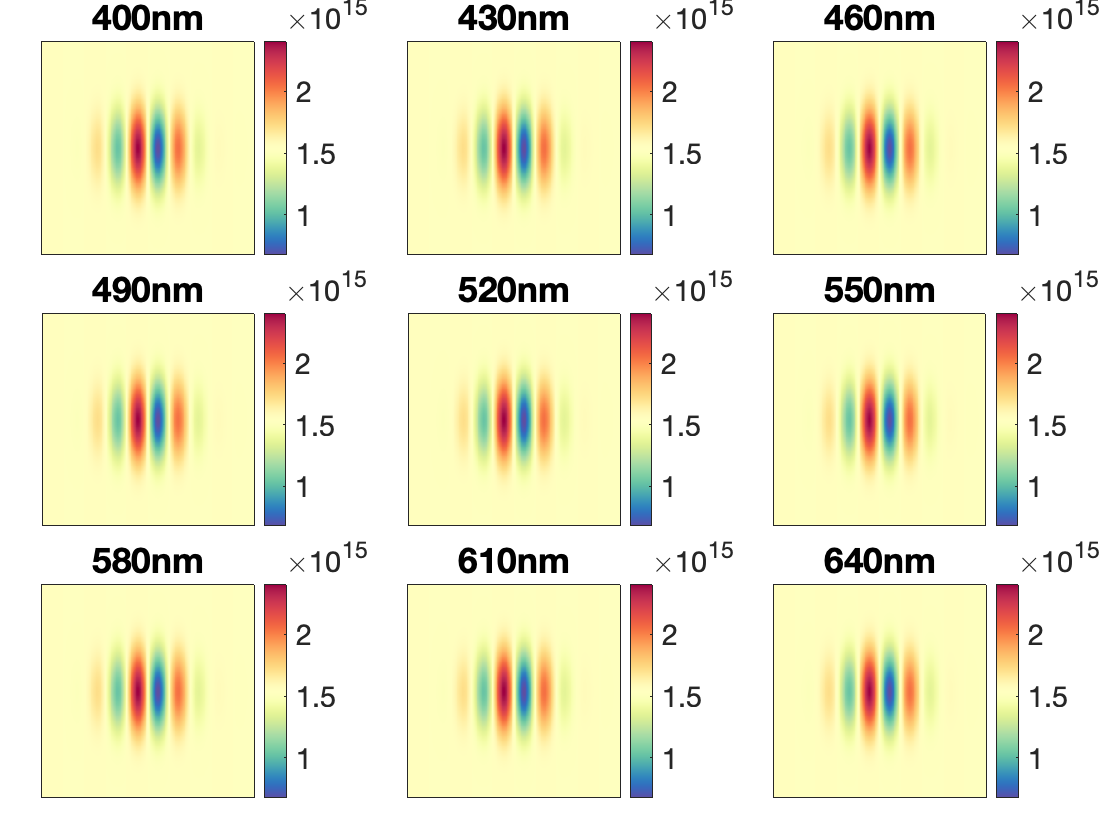

% retrieve the spectral radiance of the scene as emitted photon rate 
% (photons/sec/sr/m2/nm)
scenePhotonRate = sceneGet(scene, 'photons');
% Retrieve wavelength support
wavelengthSupport = sceneGet(scene, 'wave');
wavelengthBandsToVisualize = 400:30:700;
visualizeSceneRadiance(spatialSupportMilliMeters, 'mm', ...
    scenePhotonRate, wavelengthSupport, wavelengthBandsToVisualize);

# **Step 3.** Create a scene object representing the stimulus as realized on the presentation display

## Step 3.1 Realize the stimulus scene onto the presentation display

% Convert the idealized stimulus scene into a scene that represents 
% the stimulus as realized by the presentation display
displayedScene = realizeSceneOnDisplay(scene, presentationDisplay);
% Give the scene a name
displayedScene = sceneSet(displayedScene, 'name', 'GABOR SCENE (displayed)');

## Step 3.2 Visualize the displayed scene

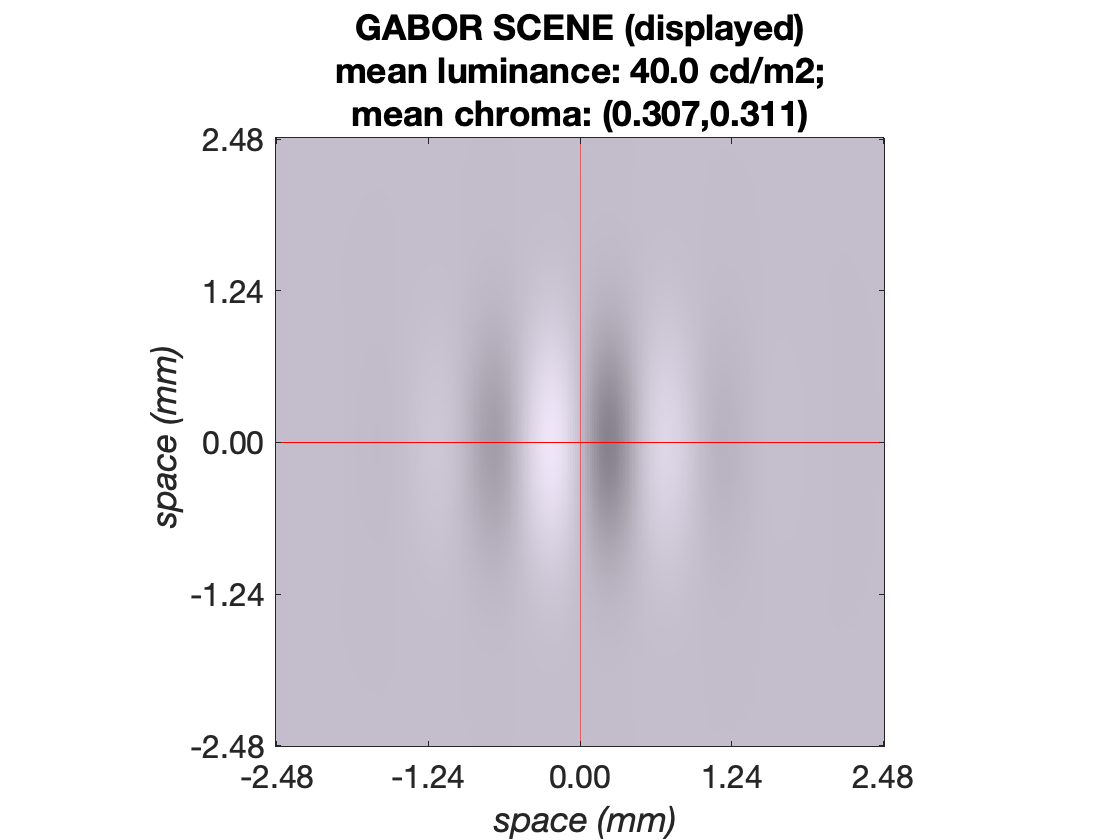

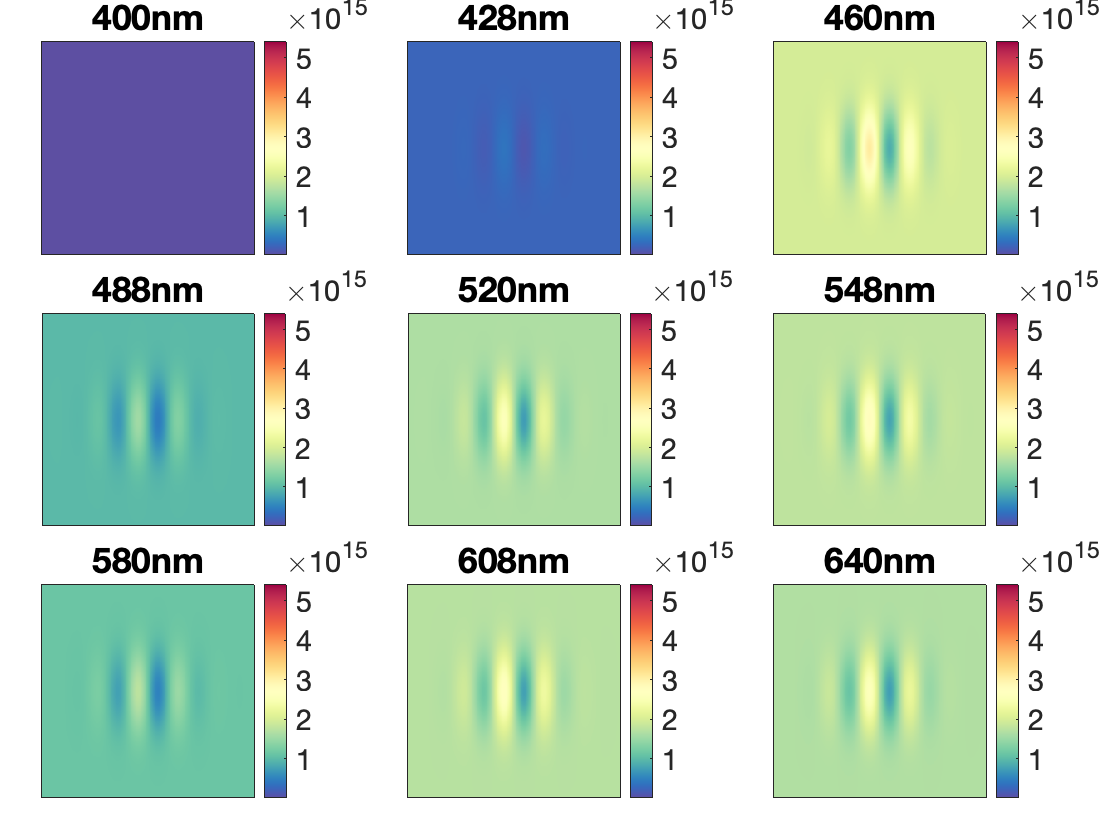

visualizeScene(displayedScene);

# Step 4. Compare scene to displayed scene

The chromaticity and the luminance of the scene and the displayed scene match very well as we expect. Here we compare the spectral radiances of the scene and of the realized scene at a single target pixel. 

% Pixel location to compare the spectral slices
targetLocationMM = [-0.15,-0.15];

## Step 4.1 Plot a spectral slice though the target pixel in the original scene

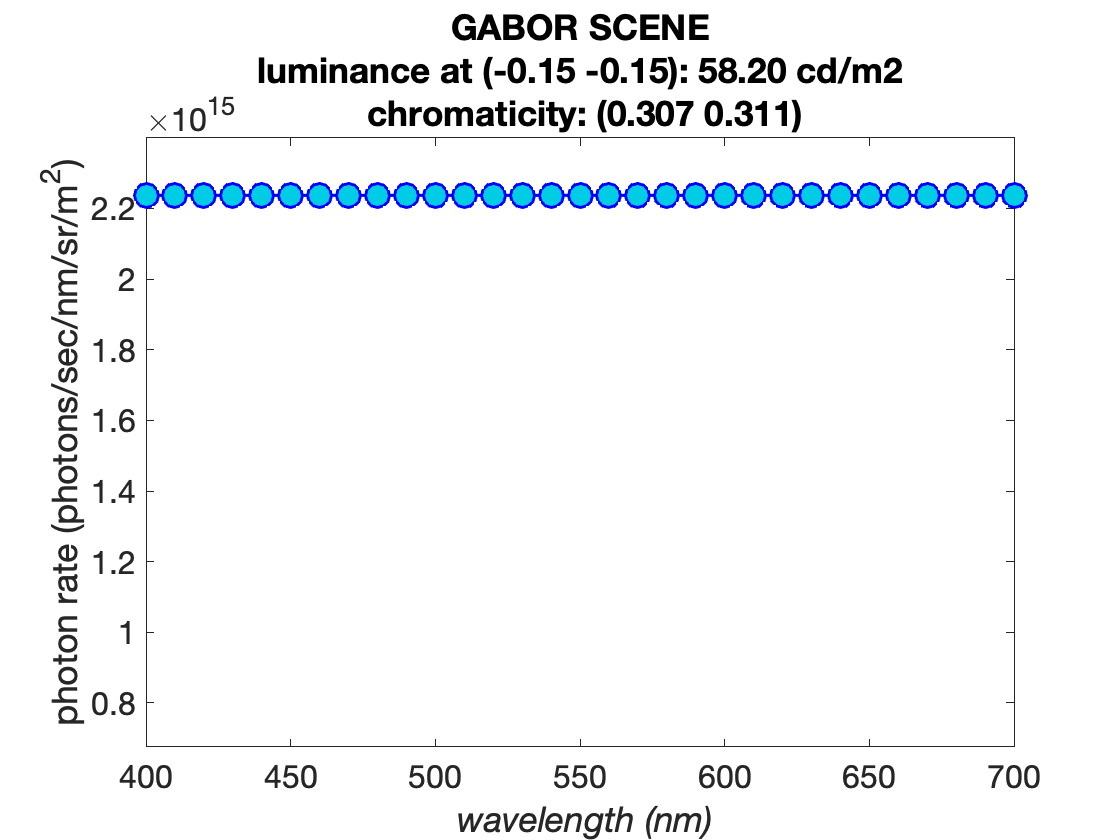

% retrieve the spectral radiance of the scene as emitted photon rate (photons/sec/m2/nm)
scenePhotonRate = sceneGet(scene, 'photons');
% retrieve the spatial support of the scene(in millimeters)
spatialSupportMilliMeters = sceneGet(scene, 'spatial support', 'mm');
% Retrieve wavelength support
wavelengthSupport = sceneGet(scene, 'wave');
visualizeSpectralRadianceSlice(spatialSupportMilliMeters, wavelengthSupport, ...
    scenePhotonRate, targetLocationMM,  sceneGet(scene, 'name'));

## Step 4.2 Plot a spectral slice though the target pixel in the displayed scene

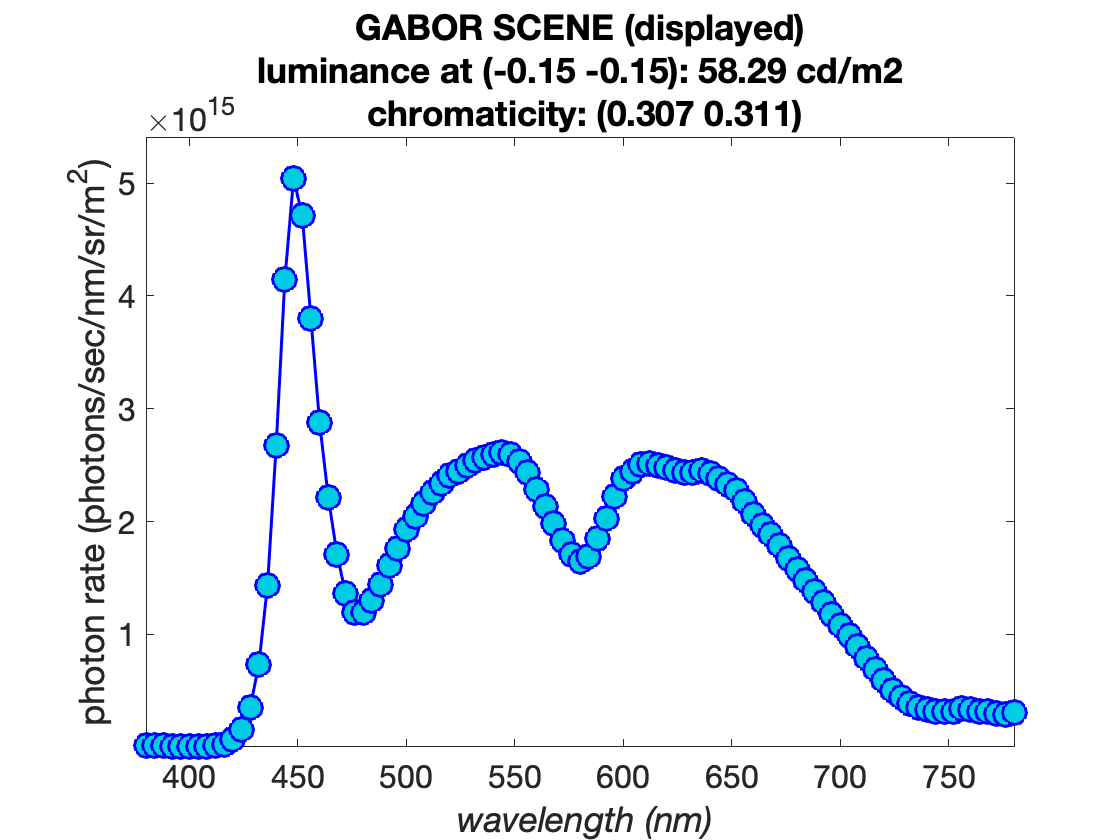

% retrieve the spectral radiance of the scene as emitted photon rate (photons/sec/m2/nm)
displayedScenePhotonRate = sceneGet(displayedScene, 'photons');
% retrieve the spatial support of the scene(in millimeters)
spatialSupportMilliMeters = sceneGet(displayedScene, 'spatial support', 'mm');
% Retrieve wavelength support
wavelengthSupport = sceneGet(displayedScene, 'wave');
visualizeSpectralRadianceSlice(spatialSupportMilliMeters, wavelengthSupport, ...
    displayedScenePhotonRate, targetLocationMM,  sceneGet(displayedScene, 'name'));

*Note: As can be seen the radiances have very different spectral distributions, as the scene is generated on an idealized system, in which we have control of emitted energy at each and every wavelength. In the real display, we only have control of three broad-band primaries with fixed spectral power distributions. So the spectral distributions of radiance emitted by the idealized and the realized scenes are quite different. This will have an impact on the corresponding retinal images, because the optics blur the scene with different point spread functions at different spectral bands.*